## Lecture 11 exercises:

#### Exercise 1:

example:

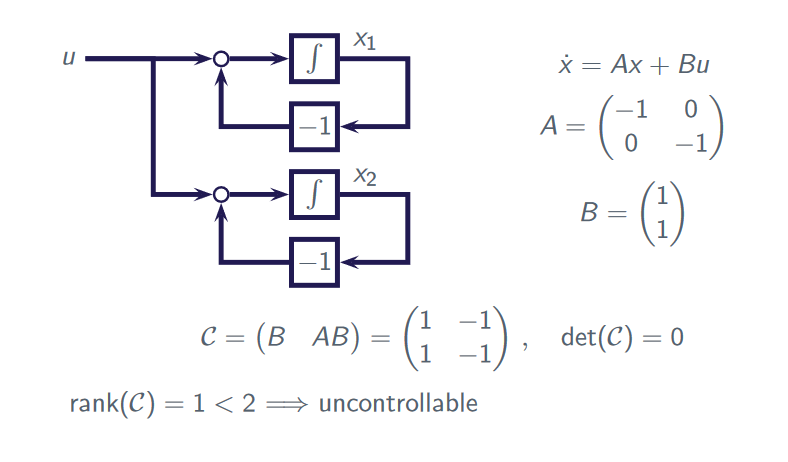

% 1)
close all
clear
A = [-1 0; 0 -1];
B = [1; 0];
A*B;
C = [1 -1; 0 0];
rank(C);
% 2)
A1 = [-1 1; 0 -1];
B1 = [1; 0];
A1*B1;
C1 = [1 -1; 0 0];
rank(C1);
% 3)
A2 = [-1 0; 1 -1];
B2 = [1; 0];
A2*B2;
C1 = [1 -1; 0 1];
rank(C1);

ans =      2


#### Exercise 2

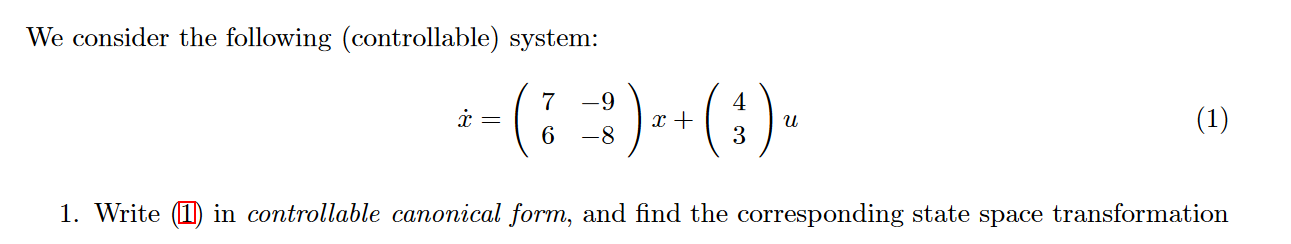

syms l
xdot = [7 -9; 6 -8];
u = [4;3];
xdot*u;
C = [4 1; 3 0];
s2 = [0 1] * inv(C);
s1 = s2*xdot;
T1 = [-3 2; 2 -1];
Tinv = [s1;s2];
T = inv(T);
Ac = Tinv*xdot*T

Ac =          -7.33333333333333          10.7777777777778
          2.66666666666667         -3.88888888888889


y = l^2 + l - 2;
Bc = Tinv*u;
% (x-1)(x+2);    


$$A_c =\left\lbrack \begin{array}{cc}
-1 & 2\\
1 & 0
\end{array}\right\rbrack ,B_c =\left\lbrack \begin{array}{c}
\;1\\
0
\end{array}\right\rbrack$$


Controllable canonoical form: $\dot{\;x_c =A_c x_c +B_c u}$

%2
Fc = [1-3 -2-2];
F = Fc*Tinv;
ex3 = xdot + u*F; %final answer nu er polerne blevet rykket ind i det stabile områdde fra tidligere

ex3 =                         -1        -0.999999999999996
                         0                        -2


## Exercise 3

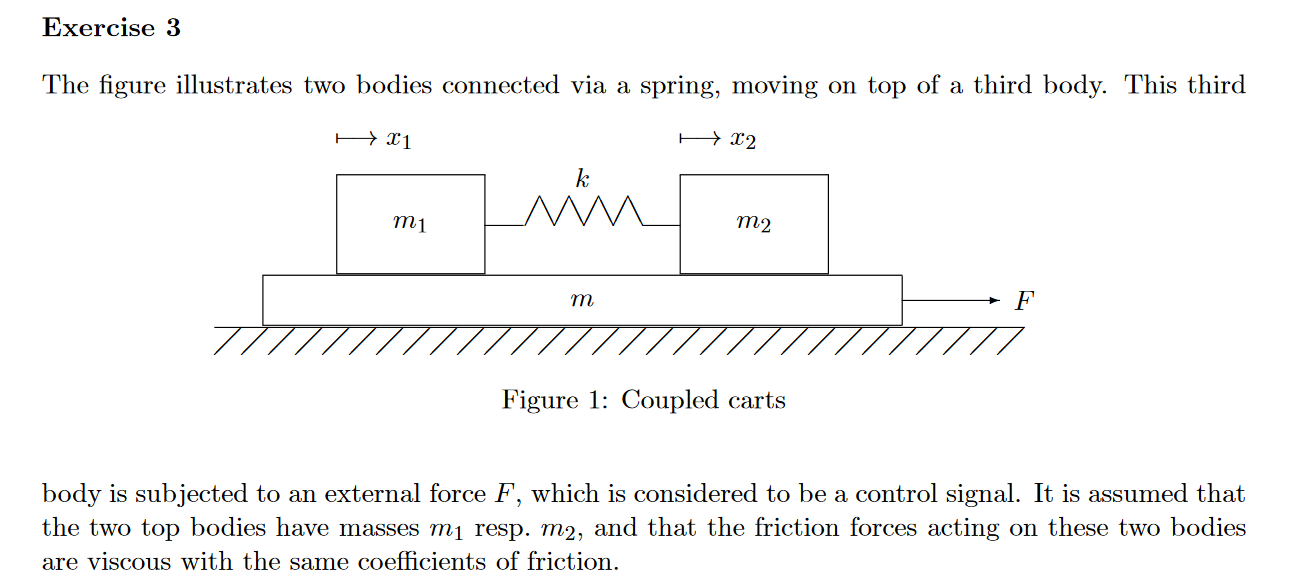

% 1.

1) At friktion kraften er større ind indvirking af F har på x1 og x2 så de to masser bliver på m deraf kan systemet nå hvilken som helst tilstand?

% 2
syms k m1 c m2

X = [0 0 1 0; 0 0 0 1; -k/m1 k/m1 -c/m1 0; k/m2 -k/m2 0 -c/m2] + [0;0;c/m1;c/m2]

$$X = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ \frac{c}{m_{1}}-\frac{k}{m_{1}} & \frac{c}{m_{1}}+\frac{k}{m_{1}} & 0 & \frac{c}{m_{1}}\\ \frac{c}{m_{2}}+\frac{k}{m_{2}} & \frac{c}{m_{2}}-\frac{k}{m_{2}} & \frac{c}{m_{2}} & 0 \end{array}\right)$$